%% 3. A script file for check the corectness of the implementation and the evaluation of the results
% Load the point of the stereo image (Mire)
P1_1 = load ('Mire/Mire1.points')

P1_1 =    240   137
   445   120
   465   119
   703   137
   442   408
   250   473
   459   410
   685   472
   241   513
   454   439


P2_2 = load ('Mire/Mire2.points')

P2_2 =     52   136
   288   119
   306   118
   519   136
   294   407
    72   472
   310   407
   508   469
    61   510
   303   437



% Load the poit of the stereo image (Rubik)
% P1_1 = load ('Rubik/Rubik1.points')
% P2_2 = load ('Rubik/Rubik2.points')

row_number = size(P1_1, 1);
ones_column = ones(row_number, 1);

% convert in homogeneous cordinate
P1 = [P1_1, ones_column]

P1 =    240   137     1
   445   120     1
   465   119     1
   703   137     1
   442   408     1
   250   473     1
   459   410     1
   685   472     1
   241   513     1
   454   439     1


P1 = P1'; % want to consider a row vector

P2 = [P2_2, ones_column]

P2 =     52   136     1
   288   119     1
   306   118     1
   519   136     1
   294   407     1
    72   472     1
   310   407     1
   508   469     1
    61   510     1
   303   437     1


P2 = P2';

% Call the function for calculate the normalized fondamental matrix 
F = EightPointsAlgorithmN(P1, P2, row_number) % Pass P1 transpose for the produìct inside the function 

U =    -0.0604   -0.0061    0.9982
    0.9980   -0.0207    0.0603
    0.0203    0.9998    0.0074


D =     0.7088         0         0
         0    0.7054         0
         0         0    0.0041


V =    -0.0033    0.0611   -0.9981
   -0.0177   -0.9980   -0.0610
    0.9998   -0.0174   -0.0044


F =    -0.0000    0.0000   -0.0003
   -0.0000    0.0000    0.0042
    0.0003   -0.0042   -0.0356



% evaluate the results of f:
% chceck the epipolar constraints x'Fx = 0,  check for every point
for i = 1:1:row_number
    result(i) = P2(:,i)' * F * P1(:,i)
end

result = 0.0094

result =     0.0094   -0.0004


result =     0.0094   -0.0004   -0.0000


result =     0.0094   -0.0004   -0.0000    0.0050


result =     0.0094   -0.0004   -0.0000    0.0050    0.0031


result =     0.0094   -0.0004   -0.0000    0.0050    0.0031    0.0097


result =     0.0094   -0.0004   -0.0000    0.0050    0.0031    0.0097   -0.0048


result =     0.0094   -0.0004   -0.0000    0.0050    0.0031    0.0097   -0.0048    0.0072


result =     0.0094   -0.0004   -0.0000    0.0050    0.0031    0.0097   -0.0048    0.0072    0.0030


result =     0.0094   -0.0004   -0.0000    0.0050    0.0031    0.0097   -0.0048    0.0072    0.0030    0.0010


result =     0.0094   -0.0004   -0.0000    0.0050    0.0031    0.0097   -0.0048    0.0072    0.0030    0.0010    0.0092


result =     0.0094   -0.0004   -0.0000    0.0050    0.0031    0.0097   -0.0048    0.0072    0.0030    0.0010    0.0092    0.0043


result =     0.0094   -0.0004   -0.0000    0.0050    0.0031    0.0097   -0.0048    0.0072    0.0030    0.0010    0.0092    0.0043    0.0021


result =     0.0094   -0.0004   -0.0000    0.0050    0.0031    0.0097   -0.0048    0.0072    0.0030    0.0010    0.0092    0.0043    0.0021    0.0099


result =     0.0094   -0.0004   -0.0000    0.0050    0.0031    0.0097   -0.0048    0.0072    0.0030    0.0010    0.0092    0.0043    0.0021    0.0099    0.0069



img1 = imread('Mire/Mire1.pgm');

img2 = imread('Mire/Mire2.pgm');

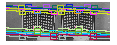


% this function allows me to visualize the epipolar line give the two
% images with the two pair of point
visualizeEpipolarLines( img1, img2, F, P1_1, P2_2);


% looking for the epipole
%needs to applicate the decomposition svd to F matrix F = UWV' and select
%the last columns of U and V

[U W V] = svd (F);
last_col_U = U(1:2,end)

last_col_U =     0.9975
    0.0711


last_col_V = V(1:2,end)

last_col_V =    -0.9977
   -0.0672
